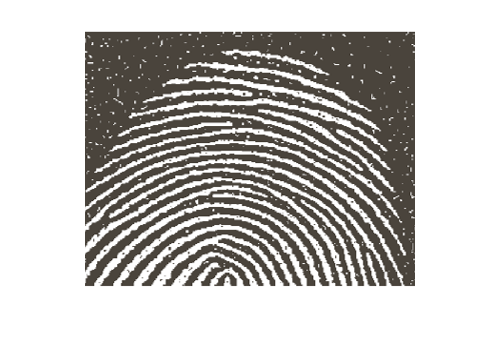

img = imread('fingerprint.png');
imshow(img);

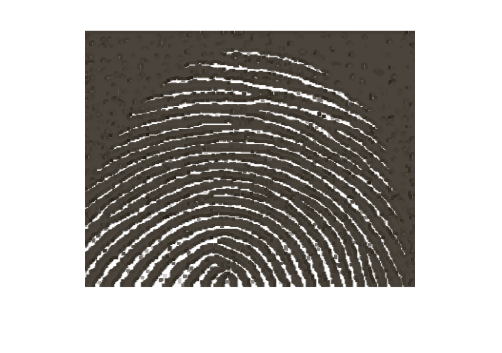

SE4 = strel('rectangle', [4 4]);
SE3 = strel('rectangle', [3 3]); 
SE2 = strel('rectangle', [2 2]);
SE1 = strel('rectangle', [1 1]);
img2 = imerode (img, SE3);
imshow(img2);

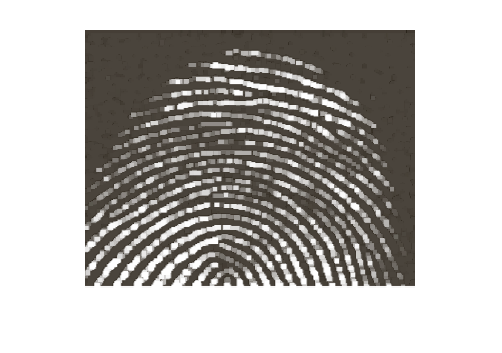

img3 = imopen(img2, SE2);
img4 = imdilate(img3, SE3);
imshow(img4);

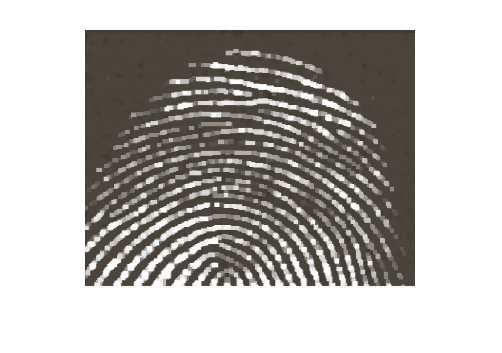

img5 = imclose(img4, SE3);
imshow(img5)

img6 = imerode(img5, SE1);
imshow(img6)